Import point cloud

data = dlmread('points3D.txt');
x_3d = data(:, 2);
y_3d = data(:, 3);
z_3d = data(:, 4);
ptCloud = pointCloud([x_3d, y_3d, z_3d], 'Color', [1, 1, 1]);

Find two-dimensional plane

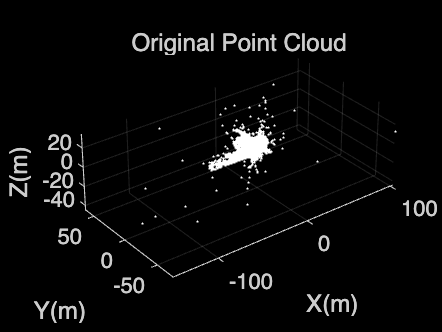

maxDistance = 0.04;
referenceVector_x = [1,0,0];
referenceVector_y = [0,1,0];
referenceVector_z = [0,0,1];
maxAngularDistance = 5;

[model1,inlierIndices_1,outlierIndices_1] = pcfitplane(ptCloud,...
         maxDistance,referenceVector_z,maxAngularDistance);
plane1 = select(ptCloud,inlierIndices_1);

% roi = [-17,15;-10,23;-4,0];
% sampleIndices = findPointsInROI(ptCloud,roi);
% 
% [model1,inlierIndices,outlierIndices] = pcfitplane(ptCloud,...
%             maxDistance,SampleIndices=sampleIndices);
% plane1 = select(ptCloud,inlierIndices);

figure;
pcshow(ptCloud)
xlabel("X(m)")
ylabel("Y(m)")
zlabel("Z(m)")
title("Original Point Cloud")

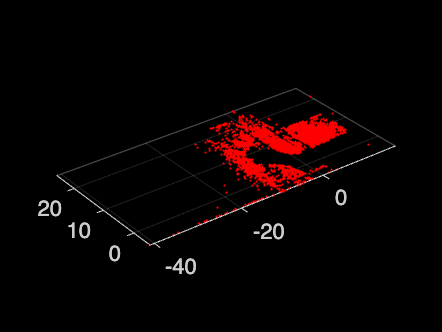

figure;
pcshow(plane1.Location,'r');

预处理获得的plane点云

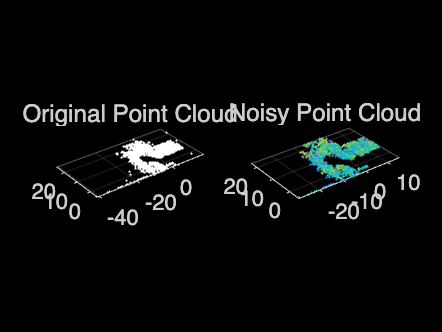

% 从点云中提取位置
locations = plane1.Location;

% 定义一个噪声级别
noiseLevel = 0.01;

% 在每个点位置上添加随机噪声
locationsNoisy = locations + noiseLevel*randn(size(locations));

% 创建一个新的点云，包含噪声
ptCloudNoisy = pointCloud(locationsNoisy);

% 使用pcoutlier函数找到离群点
distanceThreshold = 1; % 设置一个阈值，你可能需要根据你的数据调整这个值
[outliers, inliers] = pcdenoise(ptCloudNoisy, 'Threshold', distanceThreshold);

% 创建一个新的点云，移除了离群点
ptCloudWithoutOutliers = select(ptCloudNoisy, inliers);


% 显示原始点云和噪声点云
figure;
subplot(1,2,1);
pcshow(plane1);
title('Original Point Cloud');
subplot(1,2,2);
pcshow(ptCloudWithoutOutliers);
title('Noisy Point Cloud');

'Manually' draw the outline and return the real world coordinates

% set(gca,'color','w');
% xlabel("X(m)")
% ylabel("Y(m)")
% zlabel("Z(m)")
% title("Plane 1")
% hold on;
% % After clicking, you need to press the Enter key
% [x_click, y_click] = ginput();
% % Draw the Contours
% plot(x_click,y_click,'LineWidth',2,'Color','b');
% hold off;
% % Print real world coordinates
% disp('X and Y coordinates of clicked points:');
% for i = 1:size(x_click, 1)
%     fprintf('Corner Point of Contours %d: X = %.2f, Y = %.2f\n', i, x_click(i), y_click(i));
% end
% % figure;
% % plot(x_click,y_click,'LineWidth',2,'Color','b');
% 
% % House model
% figure;
% 
% z_zeros = zeros(size(x_click))
% % Base of the house
% patch(x_click,y_click,z_zeros,'b');
% 
% % Make the figure look 3D
% zlim([0, inf]);
% grid on;
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% view(3);




'Automatically' draws the outline and returns the real world coordinates

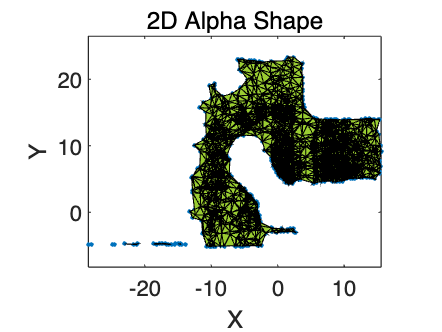

X = ptCloudWithoutOutliers.Location(:,1);
Y = ptCloudWithoutOutliers.Location(:,2);
% Compute the alpha shape
alpha = 1.3;  % Adjust this parameter to control the tightness of the boundary
shp = alphaShape(X, Y, alpha);

% Plot the points
figure;
plot(X, Y, '.');

% Hold on so we can plot the shape on top
hold on;

% Plot the alpha shape
plot(shp);

% Title and labels
title('2D Alpha Shape');
xlabel('X');
ylabel('Y');

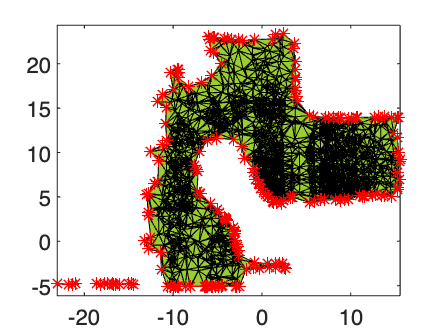


% Extract the boundary points
B = boundaryFacets(shp);

% The returned matrix B contains indices into the Points property of the
% alphaShape object. These indices define the edges of the alpha shape. You
% can use these indices to get the points on the boundary.

% Get the points on the boundary
boundaryPoints = shp.Points(B(:,1), :);

% Now boundaryPoints should be a Mx2 matrix where M is the number of points
% on the boundary. Each row contains the x and y coordinates of a point on
% the boundary. These points should be in counterclockwise order.

% Plot the alpha shape and the boundary points
figure;
plot(shp);
hold on;
plot(boundaryPoints(:,1), boundaryPoints(:,2), 'r*');
hold off;

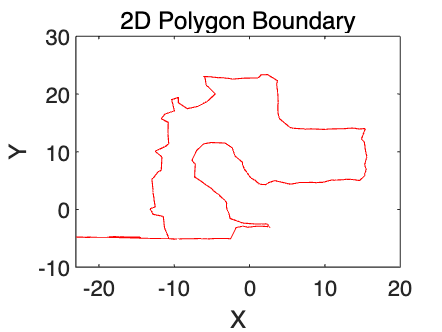

figure;
plot(boundaryPoints(:,1), boundaryPoints(:,2), 'r-');
title('2D Polygon Boundary');
xlabel('X');
ylabel('Y');